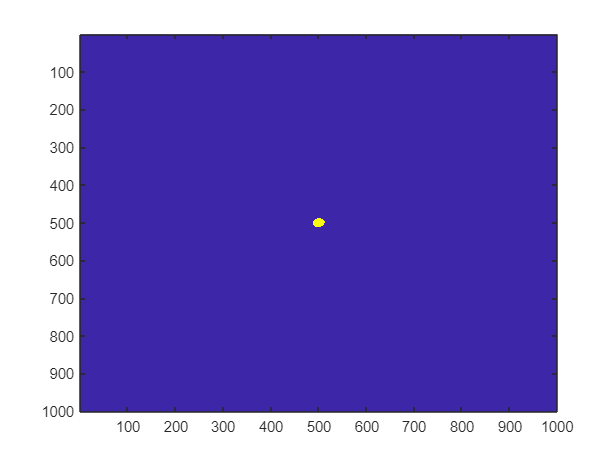


bw=GetRandomEllipseImage(1);
imagesc(bw)

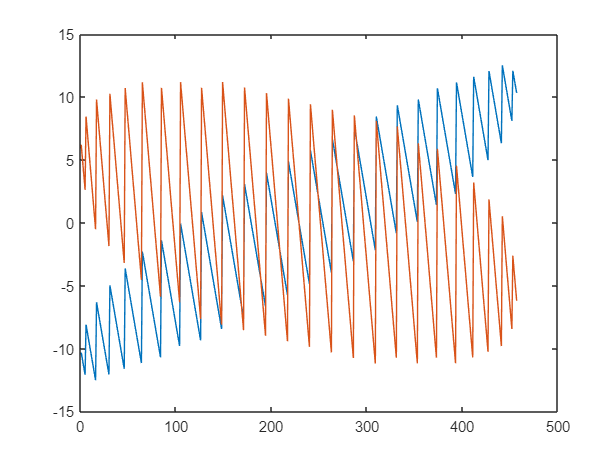

[r,c]=find(bw);
x = r - mean(r);
y = c - mean(c);
[U,S,V] = svd([x,y],'econ');
xyp = [x y]*V;
plot(xyp)

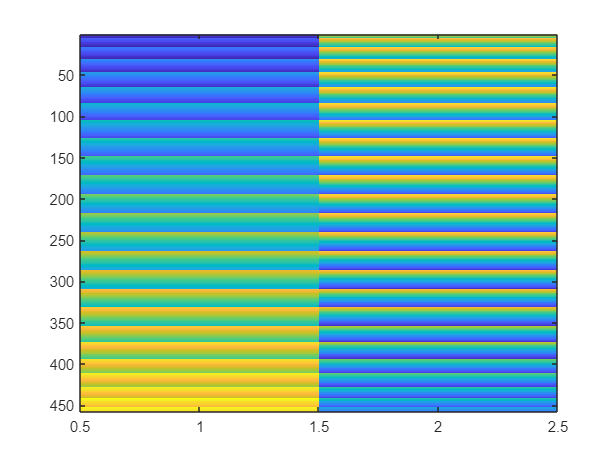

imagesc(xyp)


theta=linspace(0,2*pi,1000);
cXp = [x y]/ V

cXp =    11.2063    4.4067
   10.7643    5.3037
   10.3223    6.2008
    9.8804    7.0978
    9.4384    7.9948
   11.6352    1.2736
   11.1932    2.1707
   10.7512    3.0677
   10.3093    3.9647
    9.8673    4.8618


cYp = [x y]/ V

cYp =    11.2063    4.4067
   10.7643    5.3037
   10.3223    6.2008
    9.8804    7.0978
    9.4384    7.9948
   11.6352    1.2736
   11.1932    2.1707
   10.7512    3.0677
   10.3093    3.9647
    9.8673    4.8618



r1 = cXp/sin(theta)' ;

Error using  / 
Matrix dimensions must agree.

r2 = cYp/cos(theta)';



% GetRandomEllipseImage(K)
% generate a logical image with K overlapping ellipses
% 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Copyright (c) 2016, Drexel University
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without
% modification, are permitted provided that the following conditions are met:
% 
% * Redistributions of source code must retain the above copyright notice, this
%   list of conditions and the following disclaimer.
% 
% * Redistributions in binary form must reproduce the above copyright notice,
%   this list of conditions and the following disclaimer in the documentation
%   and/or other materials provided with the distribution.
% 
% * Neither the name of PixelRep nor the names of its
%   contributors may be used to endorse or promote products derived from
%   this software without specific prior written permission.
% 
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS"
% AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE
% IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE
% DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE
% FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL
% DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR
% SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER
% CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY,
% OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE
% OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function bw=GetRandomEllipseImage(K)

IMSIZE=1000;
mu1=[500,500];

bw=logical(zeros(IMSIZE));

pts={};
ptsEdge={};
bValidEllipse=0;

while ~bValidEllipse
    for kk=1:K
        [pts{kk} ptsEdge{kk}] = GetRandomEllipsePts(mu1,IMSIZE);
    end
    
    % place each ellipse
    for kk=2:K
        ptsCombined=vertcat(pts{1:kk-1});
        idxK = 1+round((length(pts{kk})-1)*rand());
        idxCombined = 1+round((length(ptsCombined)-1)*rand());
        offset = ptsCombined(idxCombined,:)-pts{kk}(idxK,:);
        pts{kk} = pts{kk} + repmat(offset,[size(pts{kk},1) 1]);
        ptsEdge{kk} = ptsEdge{kk}+repmat(offset,[size(ptsEdge{kk},1) 1]);
    end
    idxPts={};
    for kk=1:K
        idxPts{kk}=sub2ind([1000,1000],pts{kk}(:,2),pts{kk}(:,1));
    end
    
    idxPtsOverlap=GetOverlap(idxPts);
    % make sure no ellipse is fully contained in another
    nNonOverlap=idxPtsOverlap(2.^[0:K-1]);
    nNonOverlap=cellfun(@length,nNonOverlap);
    if all(nNonOverlap~=0)
        bValidEllipse=1;
    end
end

ptsCombined=round(vertcat(pts{:})); 
idxCombined=sub2ind(size(bw),ptsCombined(:,2),ptsCombined(:,1));
bw(idxCombined)=1;
end

function [pts, ptsEdge] = GetRandomEllipsePts(mu,IMSIZE)

RADII_0=20;
RADII_1=10; 

r1 = RADII_0+2*RADII_1*rand()-RADII_1;
r2 = RADII_0+2*RADII_1*rand()-RADII_1;

theta = 2*pi*rand();
% [r1 r2 theta]
cv = [r1^2 0;0 r2^2];

[pts]=genEllipse(mu,cv);
ptsEdge = genEllipse(mu,cv,1,0);

pts=pts-repmat(mu,[size(pts,1) 1]);
ptsEdge = ptsEdge-repmat(mu,[size(ptsEdge,1) 1]);
rotate = [cos(theta) -sin(theta);sin(theta) cos(theta)];

pts=pts*rotate;
ptsEdge=ptsEdge*rotate;

pts=pts+repmat(mu,[size(pts,1) 1]);
ptsEdge=ptsEdge+repmat(mu,[size(ptsEdge,1) 1]);

bw=false(IMSIZE);
idx=sub2ind(size(bw),round(ptsEdge(:,2)),round(ptsEdge(:,1)));

bw(idx)=1;

bw = imfill(bw,'holes');
[r c]=find(bw);
pts=[c r];
end

function idxPtsOverlap=GetOverlap(idxPts)

K=length(idxPts);
idxPtsOverlap={};
% idxPtsOverlap goes from 1..2^K-1
% the index is a binary vector specifying the overlap regions,
% e.g. 1,2,4,8, etc are points only in ellipses 1,2,3,4 etc.
% 3 is in 1 and 2, 5 is in 4 and 1, etc.
% no overlap between superset and subset pixels
for n=1:(2^K)-1
    rgBinary=dec2bin(n);
    idx1 = find(rgBinary);
    if length(idx1)==1
        idxPtsOverlap{n}=idxPts{idx1};
        continue
    end
    nIntersect=idxPts{idx1(1)};
    for i=2:length(idx1)
        nIntersect=intersect(nIntersect,idxPts{idx1(i)});
    end
    idxPtsOverlap{n}=nIntersect;
end

for i=1:length(idxPtsOverlap)
    for j=1:length(idxPtsOverlap);
        if i==j
            continue
        end
        rgBinaryI = de2bi(i);
        rgBinaryJ = de2bi(j);
        
        if length(find(rgBinaryI))<length(find(rgBinaryJ))
            idxPtsOverlap{i}=setdiff(idxPtsOverlap{i},idxPtsOverlap{j});
        end
    end
end
end

function [pts_xy, bw]=genEllipse(mu_xy,cv,c,bFill)

if nargin<3
    c=1;
end

if nargin<4
    bFill=1;
end
bw=false(1000);
    
theta=linspace(0,2*pi,1000);
[evec, eval]=eig(cv);
[eval, order] = sort(diag(eval),'descend');
evec=evec(:,order);

a1 = sqrt(eval(1))*c*evec(:,1);
a2 = sqrt(eval(end))*c*evec(:,2);

x = (mu_xy(1) + a1(1)*sin(theta) + a2(1)*cos(theta));
y = (mu_xy(2) + a1(2)*sin(theta) + a2(2)*cos(theta));
x = max(x, 1);
y = max(y, 1);
x = min(x, 1000);
y = min(y, 1000);

pts_xy=[x' y'];
idx=sub2ind(size(bw),round(y),round(x));
bw(idx)=1;

if bFill
    bw = imfill(bw,'holes');
    [r c]=find(bw);
    pts_xy=[c r];
end
end